# Clearing workspace

clear
close all
clc

## Definição de Parâmetros

% Parameters for testing
SNR = -15:1:15; 
NTrial = 100 ;
NPulse = 10;
Pfa = 1e-3;
% Given Parameters
Pt = 1e5; % Potência de Transmissão
fc = 3e9; % Frequência de Transmissão
Tau = 2e-6; % Duração do Pulso
L = 6; % Perdas do Radar em dB
Gt = 0; % Ganho de Transmissão em dB
Gr = 0; % Ganho de Recepção em dB
Rt = 6e4; % Base Range for SNR calculation
Sigma = 1; % RCS
% Complementry Parameters
c = 3e8; % Lightspeed aproximation
Lambda = c/fc; % Wavelenght
fs = 2/Tau; % Sample Rate
fpr = 0.004/Tau; % Pulse Repetition Interval for 0,4% Duty Cicle
NoFig = 0; %Noise Figure
% Required Noise Temperature given desired SNRs
No = (Pt*db2pow(Gr+Gt)*Lambda^2*Sigma)./((4*pi)^3*Rt^4*db2pow(L+SNR));
NoTemp = (No)/(physconst('Boltzmann')*db2pow(NoFig)*1/Tau);
% keep memory requirements low
BuffSize = NPulse*1000;

## Transmissão

Aqui são definidos os objetos necessários para realizar a transmissão dos pulsos.

% Waveform
Waveform = phased.RectangularWaveform('SampleRate',fs,'PulseWidth',Tau,...
    'PRF',fpr,'OutputFormat','Pulses','NumPulses',1);
% Antenna
Antenna = phased.IsotropicAntennaElement('FrequencyRange',...
    [1e9 10e9]);
% Antenna Plataform
AntennaPlatform = phased.Platform('InitialPosition',[0;0;0],'Velocity',[0;0;0]);
% Transmitter
Transmitter = phased.Transmitter('PeakPower',Pt,'Gain',Gt,...
    'LossFactor',L,'InUseOutputPort',true,...
    'CoherentOnTransmit',true);
% Radiator
Radiator = phased.Radiator('Sensor',Antenna,...
    'PropagationSpeed',c,...
    'OperatingFrequency',fc);

## Modelo do Alvo

Neste bloco, o alvo é definido como não-flutuante e estacionário.

% Target Model
Target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',Sigma,'PropagationSpeed',c,...
    'OperatingFrequency',fc);
% Target Plataform
TargetPlataform = phased.Platform('InitialPosition',[Rt; 0; 0],...
    'Velocity',[0;0;0]);

## Propagação dos Pulsos

Aqui é definido o objeto que representa o modelo de propagação de onda sobre o espaço livre, a fim de simular efeitos atmosféricos no sinal transmitido.

Channel = phased.FreeSpace('PropagationSpeed',c,...
    'OperatingFrequency',fc,'TwoWayPropagation',true,...
    'SampleRate',fs);

## Recepção

Neste bloco de código é modelado o receptor do radar. Este deve amplificar o sinal recebido por um fator $G_r$.

% Waveform Collection
Collector = phased.Collector('Sensor',Antenna,...
    'PropagationSpeed',c,...
    'Wavefront','Plane','OperatingFrequency',fc);
% Receiver
Receiver = phased.ReceiverPreamp('Gain',Gr,'NoiseMethod','Noise temperature',...
        'ReferenceTemperature',NoTemp(1),'SampleRate',fs,...
        'NoiseFigure',NoFig,'EnableInputPort',true);

## Definições Auxiliares

Aqui são definidas variáveis utilizadas posteriormente, bem como é definido o filtro de recepção casado.

% Time steps and grid
FastTimeGrid = unigrid(0,1/fs,1/fpr,'[)');
RangeGates = c*FastTimeGrid/2;
% Matched Filter
MatchedFilter = phased.MatchedFilter(...
   'Coefficients',getMatchedFilter(Waveform),...
   'GainOutputPort',true);
% Get group delay of matched filter
GroupDelay = length(MatchedFilter.Coefficients)-1;

## Transmissão, Movimentação do Alvo, Recepção e Integração.

Aqui o sinal é transmitido, refletido nos alvos em movimento, coletado e amplificado no receptor. O sinal recebido é então entregue ao filtro casado, a fim de amplificar os pulsos referentes a alvos. Em seguida, a saída do filtro casado é replicada cinco vezes. Dessas, quatro réplicas são entregues a quatro integradores distintos: não-coerente, coerente, binário e recursivo. A última réplica é utilizada na detecção sem integração. 

% for fix Tx
AntennaPosition = AntennaPlatform.InitialPosition;
AntennaVelocity = AntennaPlatform.Velocity;
% for fix target
TargetPosition = TargetPlataform.InitialPosition;
TargetVelocity = TargetPlataform.Velocity;
% Range and Angle to Target
[TargetRange,TargetAngle] = rangeangle(TargetPosition,AntennaPosition);
RangeIndex = val2ind(TargetRange,RangeGates(2)-RangeGates(1),RangeGates(1));
% for fix PRF waveform
SigWav = step(Waveform);
% for coherent transmition
[SigTx,TxStatus] = step(Transmitter,SigWav);
% for unchanging radiation angle
SigRad = step(Radiator,SigTx,TargetAngle);
% for unchanging range to target
SigProp = step(Channel,SigRad,AntennaPosition,TargetPosition,...
    AntennaVelocity,TargetVelocity);
% for nonfluctuating target
SigTgt = step(Target,SigProp);
% for unchanging angle to target
SigCol = step(Collector,SigTgt,TargetAngle);
% Allocate arrays
SigRx = zeros(size(RangeGates,2),BuffSize);
SigNonInt = zeros(size(RangeGates,2),BuffSize/NPulse);
SigCoInt = zeros(size(RangeGates,2),BuffSize/NPulse);
SigNcInt = zeros(size(RangeGates,2),BuffSize/NPulse);
SigBi = zeros(size(RangeGates,2),BuffSize/NPulse);
SigRec = zeros(size(RangeGates,2),BuffSize/NPulse);
K = zeros(NPulse,1);
H1Co = zeros(1,NTrial);
H0Co = zeros(1,NTrial);
H1Nc = zeros(1,NTrial);
H0Nc = zeros(1,NTrial);
H1CoInt = zeros(1,NTrial);
H0CoInt = zeros(1,NTrial);
H1NcInt = zeros(1,NTrial);
H0NcInt = zeros(1,NTrial);
H1Bi = zeros(1,NTrial);
H0Bi = zeros(1,NTrial);
H1K = zeros(1,NTrial);
H0K = zeros(1,NTrial);
SimPdCo = zeros(1,length(SNR));
SimPfaCo = zeros(1,length(SNR));
SimPdNc = zeros(1,length(SNR));
SimPfaNc = zeros(1,length(SNR));
SimPdCoInt = zeros(1,length(SNR));
SimPfaCoInt = zeros(1,length(SNR));
SimPdNcInt = zeros(1,length(SNR));
SimPfaNcInt = zeros(1,length(SNR));
SimPdBi = zeros(1,length(SNR));
SimPfaBi = zeros(1,length(SNR));
SimPdK = zeros(1,length(SNR));
SimPfaK = zeros(1,length(SNR));
% buferize
NBuff = floor((NPulse*NTrial)/BuffSize);
NRem = (NPulse*NTrial) - NBuff*BuffSize;
PowCoInt = zeros(NBuff,100);
PowNcInt = zeros(NBuff,100);
for k=1:length(SNR)
    release(Receiver)
    Receiver.ReferenceTemperature = NoTemp(k);
    for m = 1:NBuff
        parfor n = 1:BuffSize
            % Receive the echo at the antenna when not transmitting
            SigRx(:,n) = step(Receiver,SigCol,~(TxStatus>0));  
        end
        % Apply Matched Filter
        [SigMf, MfGain] = step(MatchedFilter,SigRx);
        % Shift the matched filter output
        SigMf = [SigMf(GroupDelay+1:end,:); SigMf(1:GroupDelay,:)];
        % Defining the Threshold for Noncoherent Detection
        ThresholdNc = (2*No(k)*db2pow(npwgnthresh(Pfa,1,'noncoherent')))*db2pow(MfGain);
        % Condition pulses for integration
        for r = 1:(BuffSize/NPulse)
            SigToInt = SigMf(:,(1:NPulse) + (r-1)*NPulse);
            % Pass on a single pulse
            SigNonInt(:,r) = SigToInt(:,1);
            % Coherentily Integrate NPulses
            SigCoInt(:,r) = pulsint(SigToInt,'coherent');
            % Noncoherentily Integrate NPulses
            Angs = angle(SigToInt) + 2*pi*randn(size(RangeGates,2),NPulse);
            SigToIntNc = abs(SigToInt).*exp(1j*Angs);
            SigNcInt(:,r) = pulsint(SigToIntNc,'noncoherent');
            % Binaraly Integrate NPulses
            SigToIntBi = abs(SigToInt);
            SigToIntBi(SigToIntBi>sqrt(ThresholdNc/4)) = 1;
            SigToIntBi(SigToIntBi<sqrt(ThresholdNc/4)) = 0;
            SigBi(:,r) = sum(SigToIntBi,2);
            % Recursively Integrate NPulses
            SigToIntK = abs(SigToInt);
            SigToIntK(SigToIntK>sqrt(ThresholdNc/4)) = 1;
            SigToIntK(SigToIntK<sqrt(ThresholdNc/4)) = 0;
            for w = 1:NPulse
               K(w,1) = 0.85^(NPulse-w);
            end
            SigRec(:,r) = SigToIntK*K;
        end
        % Extract desired information
        H1Co((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(RangeIndex,:);
        H0Co((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(2,:);
        H1Nc((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(RangeIndex,:);
        H0Nc((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(2,:);
        H1CoInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigCoInt(RangeIndex,:);
        H0CoInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigCoInt(2,:);
        H1NcInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNcInt(RangeIndex,:);
        H0NcInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNcInt(2,:);
        H1Bi((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigBi(RangeIndex,:);
        H0Bi((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigBi(2,:);
        H1K((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigRec(RangeIndex,:);
        H0K((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigRec(2,:);
    end
    if (NRem > 0)
        parfor n = 1:NRem
            % Receive the echo at the antenna when not transmitting
            SigRx(:,n) = step(Receiver,SigCol,~TxStatus);
        end
        % Apply Matched Filter
        [SigMf, MfGain] = step(MatchedFilter,SigRx);
        % Shift the matched filter output
        SigMf = [SigMf(GroupDelay+1:end,:); SigMf(1:GroupDelay,:)];
        % Defining the Threshold for Noncoherent Detection
        ThresholdNc = (2*No(k)*db2pow(npwgnthresh(Pfa,1,'noncoherent')))*db2pow(MfGain);
        % Condition pulses for integration
        for r = 1:(BuffSize/NPulse)
            SigToInt = SigMf(:,(1:NPulse) + (r-1)*NPulse);
            % Pass on a single pulse
            SigNonInt(:,r) = SigToInt(:,1);
            % Coherentily Integrate NPulses
            SigCoInt(:,r) = pulsint(SigToInt,'coherent');
            % Noncoherentily Integrate NPulses
            Angs = angle(SigToInt) + 2*pi*randn(size(RangeGates,2),NPulse);
            SigToIntNc = abs(SigToInt).*exp(1j*Angs);
            SigNcInt(:,r) = pulsint(SigToIntNc,'noncoherent');
            % Binaraly Integrate NPulses
            SigToIntBi = abs(SigToInt);
            SigToIntBi(SigToIntBi>sqrt(ThresholdNc/4)) = 1;
            SigToIntBi(SigToIntBi<sqrt(ThresholdNc/4)) = 0;
            SigBi(:,r) = sum(SigToIntBi,2);
            % Recursively Integrate NPulses
            SigToIntK = abs(SigToInt);
            SigToIntK(SigToIntK>sqrt(ThresholdNc/4)) = 1;
            SigToIntK(SigToIntK<sqrt(ThresholdNc/4)) = 0;
            for w = 1:NPulse
               K(w,1) = 0.85^(NPulse-w);
            end
            SigRec(:,r) = SigToIntK*K;
        end
        % Extract desired information
        H1Co((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(RangeIndex,:);
        H0Co((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(2,:);
        H1Nc((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(RangeIndex,:);
        H0Nc((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNonInt(2,:);
        H1CoInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigCoInt(RangeIndex,:);
        H0CoInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigCoInt(2,:);
        H1NcInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNcInt(RangeIndex,:);
        H0NcInt((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigNcInt(2,:);
        H1Bi((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigBi(RangeIndex,:);
        H0Bi((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigBi(2,:);
        H1K((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigRec(RangeIndex,:);
        H0K((1:BuffSize/NPulse) + (m-1)*BuffSize/NPulse) = SigRec(2,:);
    end

## Aplicação dos Limiares e Resultados da Simulação

Após realizadas as integrações, os alvos são detectados por meio do emprego de limiares projetados para cada integrador de forma a gerar a taxa de falso alarme fixa em $10^{-3}$. Para cada SNR testada, várias detecções são feitas a fim de gerar uma boa previsão da verdadeira probabilidade de detecção para cada sistema. 

Por fim, uma figura apresenta as diferentes curvas característica de operação do receptor (ROC) para as diferentes integrações com dez pulsos. Além disso, também são apresentadas as ROCs das detecções coerente e não-coerente sem integração. Usando dez pulsos em cada integração, verfica-se os seguintes ganhos, à probabilidade de detecção fixa $P_d=0.9$:

- Ganho entre detecção com integração coerente e detecção não-coerente sem integração: $11 \mathrm{dB}$

- Ganho entre detecção com integração coerente e detecção coerente sem integração: $10 \mathrm{dB}$

- Ganho entre detecção com integração coerente e detecção com integração não-coerente: $3.63 \mathrm{dB}$

- Ganho entre detecção com integração coerente e integração binária (com limiar de quantização binária obtido pela função 'binaryintloss'): $5.13 \mathrm{dB}$

- Ganho entre detecção com integração coerente e integração recursiva: $5.83 \mathrm{dB}$

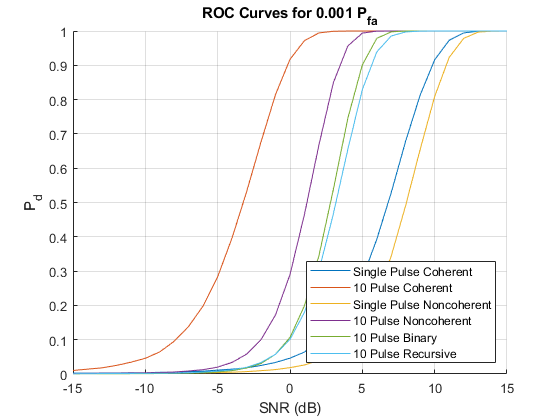

    % Coherent Detector
    H1Co = real(H1Co);%*exp(-1j*4*pi*Rt/Lambda));
    H0Co = real(H0Co);%*exp(-1j*4*pi*Rt/Lambda));
    H1CoInt = real(H1CoInt);%*exp(-1j*4*pi*Rt/Lambda));
    H0CoInt = real(H0CoInt);%*exp(-1j*4*pi*Rt/Lambda));
    % Noncoherent Detector
    H1Nc = abs(H1Nc);
    H0Nc = abs(H0Nc);
    H1NcInt = abs(H1NcInt);
    H0NcInt = abs(H0NcInt);
    % Defining the Remaining Threshold
    ThresholdNcInt = (2*No(k)*db2pow(npwgnthresh(Pfa,NPulse,'noncoherent')))...
        *db2pow(MfGain);
    ThresholdCo = (2*No(k)*db2pow(npwgnthresh(Pfa,1,'coherent')))*db2pow(MfGain);
    ThresholdCoInt = (2*No(k)*db2pow(npwgnthresh(Pfa,NPulse,'coherent')))...
        *db2pow(MfGain);
    % Estimate Pd
    SimPdNc(k) = sum(H1Nc >= sqrt(ThresholdNc))/(NTrial);
    SimPfaNc(k) = sum(H0Nc >= sqrt(ThresholdNc))/(NTrial);
    SimPdCo(k) = sum(H1Co >= sqrt(ThresholdCo))/(NTrial);
    SimPfaCo(k) = sum(H0Co >= sqrt(ThresholdCo))/(NTrial);
    SimPdCoInt(k) = sum(H1CoInt >= sqrt(ThresholdCoInt))/(NTrial);
    SimPfaCoInt(k) = sum(H0CoInt >= sqrt(ThresholdCoInt))/(NTrial);
    SimPdNcInt(k) = sum(H1NcInt >= sqrt(ThresholdNcInt))/(NTrial);
    SimPfaNcInt(k) = sum(H0NcInt >= sqrt(ThresholdNcInt))/(NTrial);
    SimPdBi(k) = sum(H1Bi >= 0.955*NPulse^(0.8))/(NTrial);
    SimPfaBi(k) = sum(H0Bi >= 0.955*NPulse^(0.8))/(NTrial);
    SimPdK(k) = sum(H1K >= 0.955*(sum(K))^(0.8))/(NTrial);
    SimPfaK(k) = sum(H0K >= 0.955*(sum(K))^(0.8))/(NTrial);
end
% Plot the ROC curve
figure(1), hold on, grid on
plot(SNR,SimPdCo)
plot(SNR,SimPdCoInt)
plot(SNR,SimPdNc)
plot(SNR,SimPdNcInt)
plot(SNR,SimPdBi)
plot(SNR,SimPdK)
title(['ROC Curves for ' num2str(Pfa) ' P_{fa}'])
xlabel('SNR (dB)')
ylabel('P_{d}')
legend('Single Pulse Coherent',[num2str(NPulse) ' Pulse Coherent'],...
    'Single Pulse Noncoherent',[num2str(NPulse) ' Pulse Noncoherent'],...
    [num2str(NPulse) ' Pulse Binary'],[num2str(NPulse) ' Pulse Recursive'],...
    'Location','southeast');